# Data analysis of localization confidence

- Does confidence reflect performance? Check correlation between error and confidence

- Do participants know the relative position between the target and response? Check whether the side of confidence bar corresponds to the target

- Is confidence modulated by cue discrepancy and cue reliability? Plot perceptual and causal confidence as a function of discrepancy (congruent, a bit incongruent, very incongruent trials); lines: low and high visual reliability

- Do people report lower confidence for incongruent trials despite identical perceptual and causal decisions? Compare confidence of perceptual and causal metamers

clear; clc; close all;
sub_slc     = 4;
ses_slc     = 1;

% manage path
cur_dir      = pwd;
[project_dir, ~]= fileparts(fileparts(cur_dir));
out_dir      = fullfile(cur_dir, 's1Fig');
data_dir     = fullfile(project_dir, 'data','biLoc');
if ~exist(out_dir,'dir') mkdir(out_dir); end

% organize data
flnm        = sprintf('biLoc_sub%i_ses%i', sub_slc, ses_slc);
load(fullfile(data_dir, flnm))

% experiment info
aud_locs    = ExpInfo.speakerLocPixel(ExpInfo.audIdx);
vis_locs    = round(ExpInfo.targetPixel);
diffs       = zeros(length(aud_locs), length(vis_locs));
for i = 1:length(aud_locs)
    for j = 1:length(vis_locs)
        diffs(i, j) = aud_locs(i) - aud_locs(j);
    end
end
disc_locs   = unique(abs(diffs));

% conditions
seq         = ExpInfo.randAVIdx;
audIdx      = ExpInfo.audIdx;
visIdx      = ExpInfo.visIdx;
cueIdx      = ExpInfo.cueIdx;
visReliIdx  = ExpInfo.visReliIdx;
num_rep     = ExpInfo.nRep;
disc        = abs(seq(1,:) - seq(2,:));
discIdx     = unique(disc);
cue_label   = {'Post-cue: A','Post-cue: V'};
rel_label   = {'High visual reliability','Low visual reliability'};

% data
target      = [Resp.target_cm] * ScreenInfo.numPixels_perCM; % convert target to pixel, center as 0
resp        = [Resp.response_pixel] - ScreenInfo.xmid; % rescale response with center as 0
err         = abs(resp - target);
conf        = [Resp.conf_radius_cm];

% organize response
[org_resp, org_conf, org_err] = deal(NaN(numel(audIdx), numel(visIdx), numel(cueIdx), numel(visReliIdx), num_rep));
for trial = 1:length(resp)
    % Find indices for each condition
    aIdx = find(audIdx == seq(1, trial));
    vIdx = find(visIdx == seq(2, trial));
    cIdx = find(cueIdx == seq(3, trial));
    rIdx = find(visReliIdx == seq(4, trial));
    
    % Find the repetition index for the current combination
    repMatrix = squeeze(org_resp(aIdx, vIdx, cIdx, rIdx, :)); % Squeeze to remove singleton dimensions
    repIdx = find(isnan(repMatrix), 1); % Find the first NaN value
    
    % Insert the response
    org_resp(aIdx, vIdx, cIdx, rIdx, repIdx) = resp(trial);
    org_conf(aIdx, vIdx, cIdx, rIdx, repIdx) = conf(trial);
    org_err(aIdx, vIdx, cIdx, rIdx, repIdx) = err(trial);
end


% organize response by discrepancy
allDiffs = unique(abs(audIdx' - visIdx));

[mean_conf, sd_conf] = deal(NaN(numel(allDiffs), numel(cueIdx), numel(visReliIdx), num_rep));
for i = 1:length(allDiffs)
    diff = allDiffs(i);
    % Find pairs of audIdx and visIdx that match this difference
    [audPairs, visPairs] = find(abs(audIdx' - visIdx) == diff);
    tempData = NaN(numel(audPairs), numel(cueIdx), numel(visReliIdx), num_rep);
    % For each pair, extract and store the corresponding data
    for j = 1:numel(audPairs)
        % Extract data for this specific audIdx and visIdx pair across all other dimensions
        tempData(j,:,:,:) = squeeze(org_conf(audPairs(j), visPairs(j), :, :, :));
    end
    
    % Store the collected data in the main cell array
    mean_conf(i,:,:,:) = mean(tempData,1);
    sd_conf(i,:,:,:) = std(tempData,[],1);

end


## Plot set up

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    251, 154, 153]./255; % light red

## Sanity check: localization response

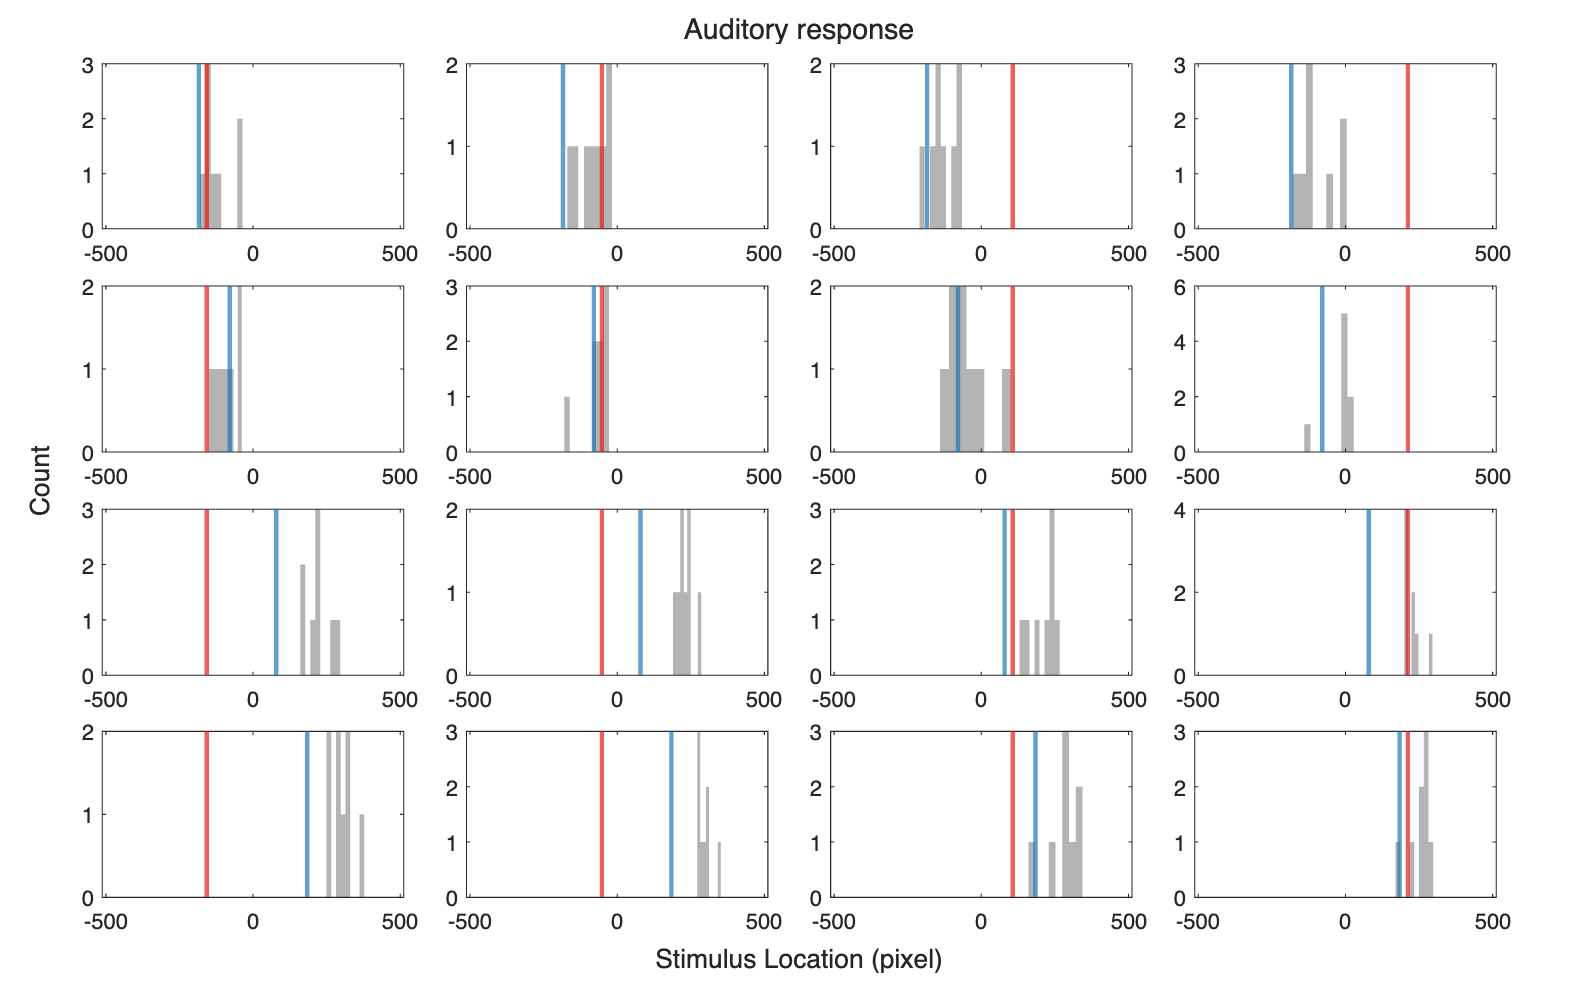

figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Auditory response')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(org_resp(a, v, 1, :, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp));
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-512, 512])
    end
end

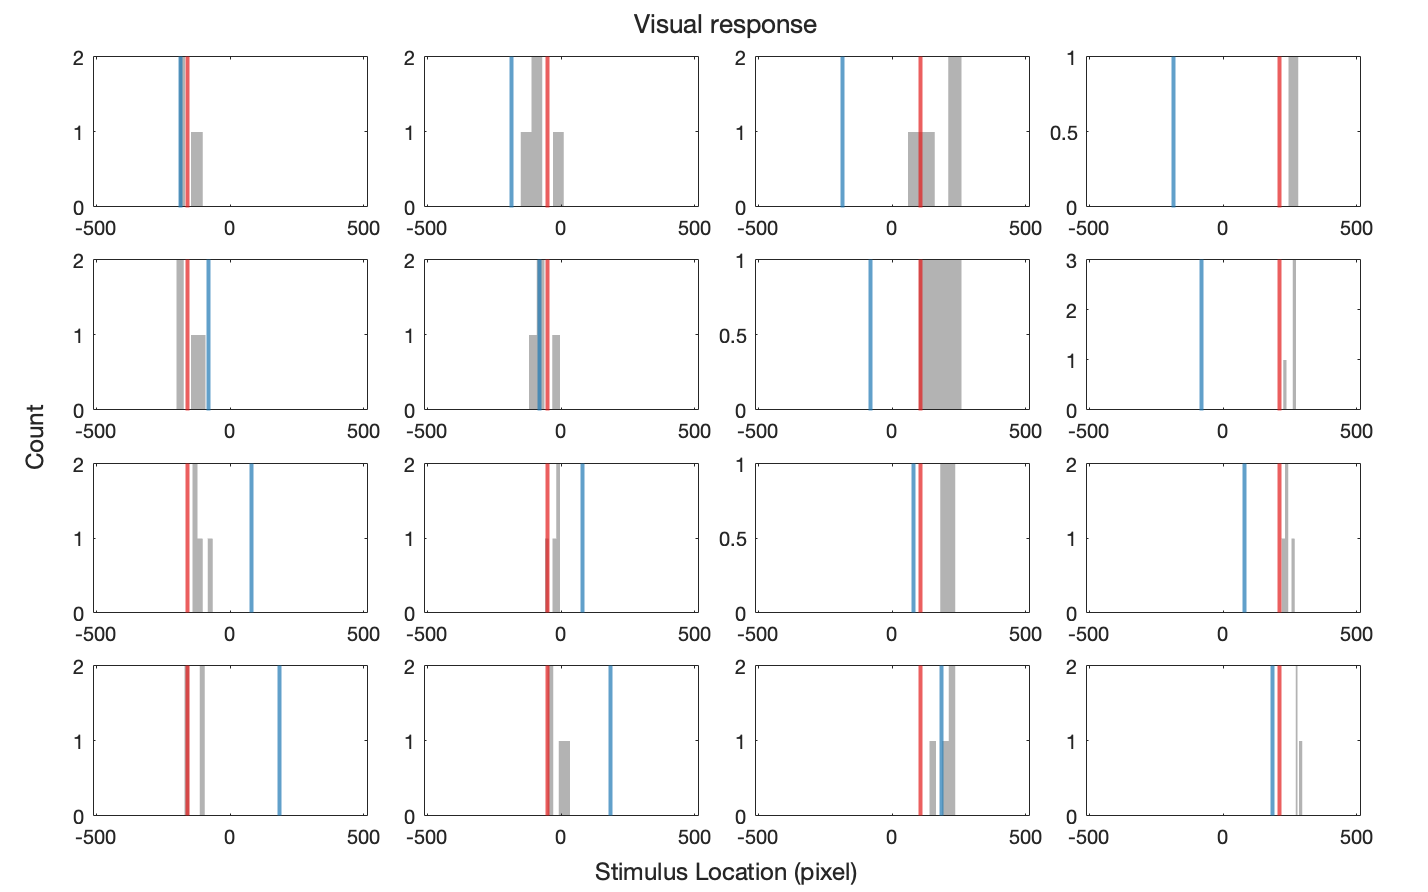


figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Visual response')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(org_resp(a, v, 2, 2, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp));
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-512, 512])
    end
end

## Sanity check: bias in congruent trials

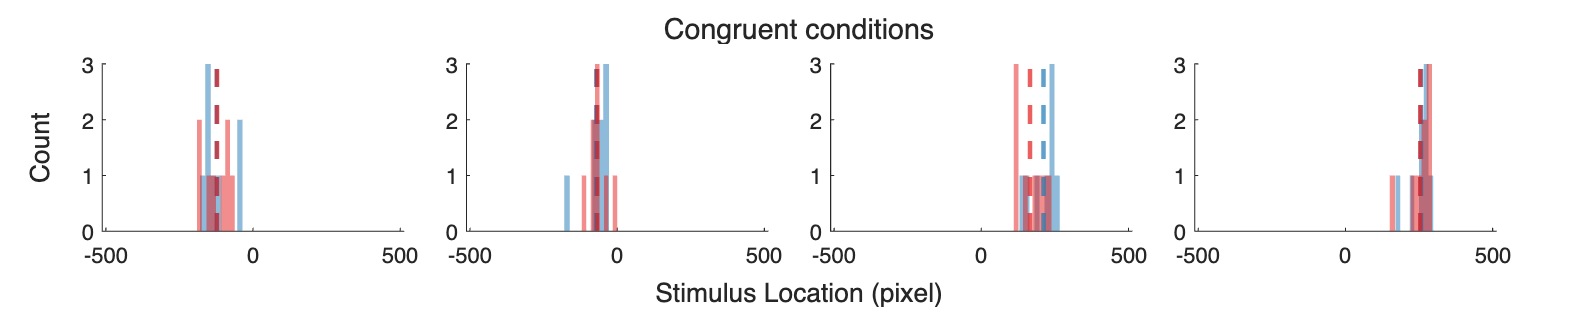

figure
set(gcf, 'Position',[0 0 1000 200])
hold on
t = tiledlayout(1, 4);
title(t, 'Congruent conditions')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for ii = 1:numel(audIdx)

    nexttile;
    hold on

    for rr = 1:numel(cueIdx)

        curr_resp = squeeze(org_resp(ii, ii, rr, :, :));
        h = histogram(curr_resp, numel(curr_resp),'FaceAlpha',0.5);
        h.FaceColor = clt(rr,:);
        h.EdgeColor = 'none';

        mean_congruent(ii, rr) = mean(curr_resp,'all');
        std_congruent(ii, rr)  = std(curr_resp,[],'all');
        xline(mean_congruent(ii, rr),'--','LineWidth',lw,'Color',clt(rr,:))

        xlim([-512, 512])
   end

end

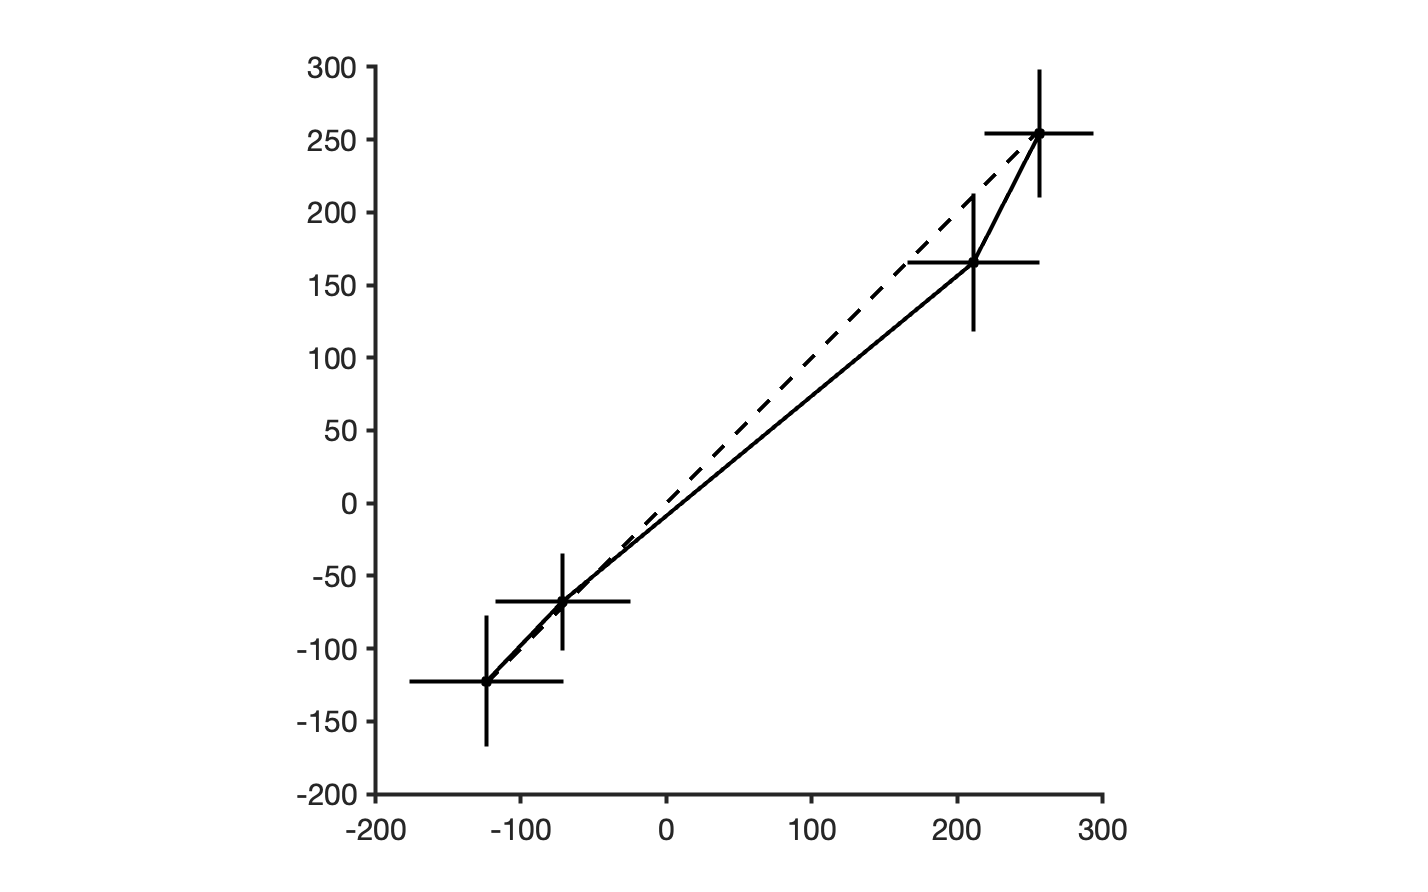


figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
set(gca, 'LineWidth', lw, 'FontSize', fontSZ, 'TickDir', 'out')
axis equal; axis square

scatter(mean_congruent(:,1),mean_congruent(:,2),'filled','k')
e1 = errorbar(mean_congruent(:,1), mean_congruent(:,2), std_congruent(:,2),'k','LineWidth',lw);
e2 = errorbar(mean_congruent(:,1), mean_congruent(:,2), std_congruent(:,1), 'k','horizontal','LineWidth',lw);
e1.CapSize = 0;
e2.CapSize = 0;
plot(max(mean_congruent,[],"all"))
maxV = max(mean_congruent(:));
minV = min(mean_congruent(:));
plot([minV, maxV],[minV, maxV],'k--','LineWidth',lw)

## Correlation between error and confidence?

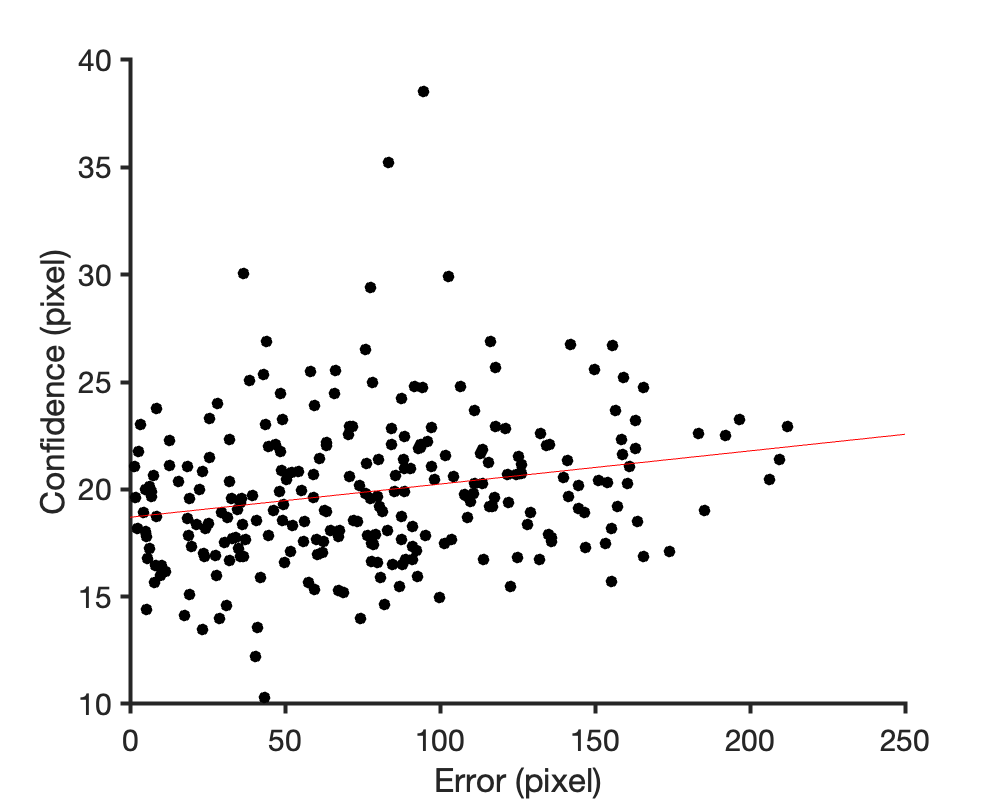

figure
set(gca, 'LineWidth', lw, 'FontSize', fontSZ, 'TickDir', 'out')
set(gcf, 'Position',[0 0 500 400])
hold on 
scatter(err, conf,'filled','k')
[linearFit, gof] = fit(err', conf', 'poly1');
plot(linearFit, 'r-');
legend off
xlabel('Error (pixel)')
ylabel('Confidence (pixel)')

## Is confidence modulated by cue discrepancy and cue reliability?

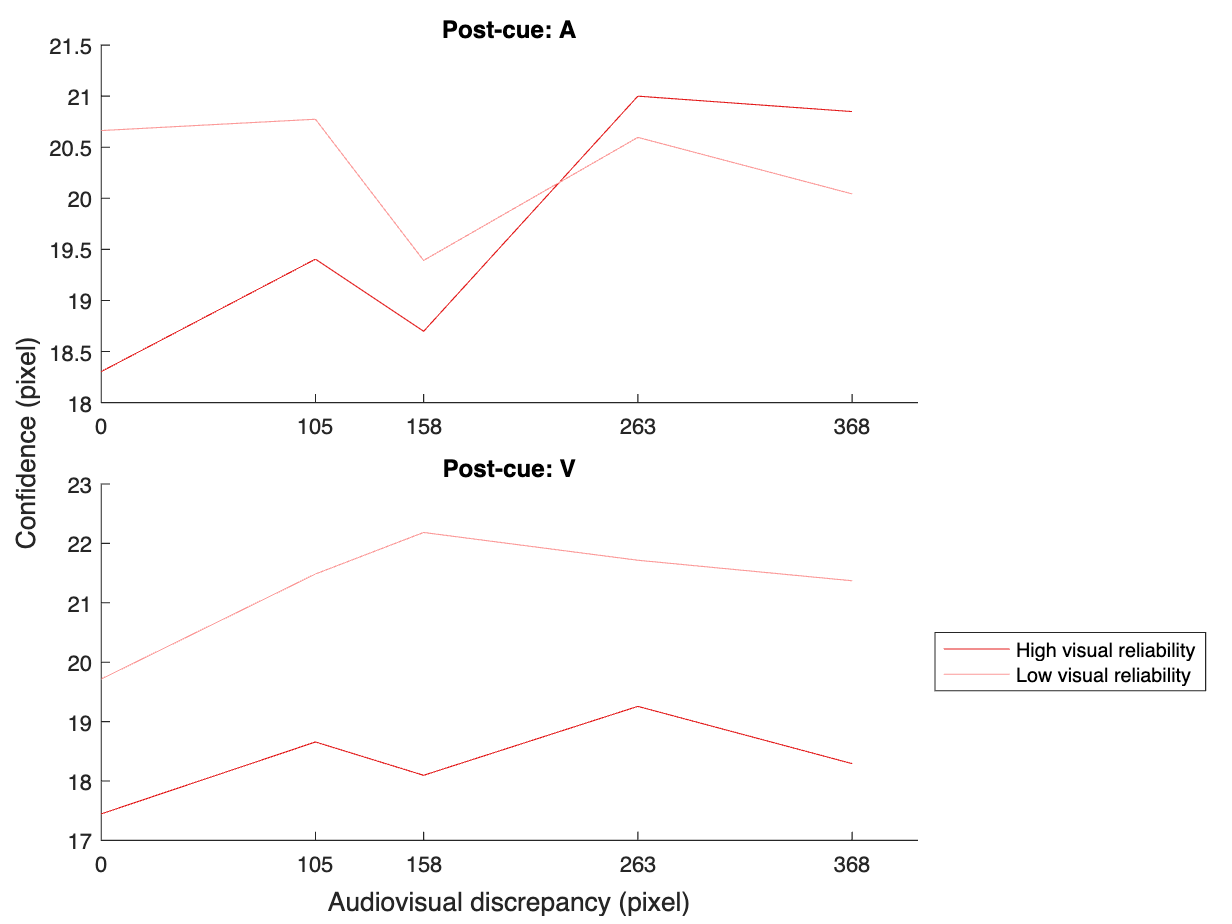

figure; hold on

t = tiledlayout(2, 1);
xlabel(t, 'Audiovisual discrepancy (pixel)');
ylabel(t, 'Confidence (pixel)');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    hold on
    for rel = 1:numel(visReliIdx)
        plot(disc_locs, squeeze(mean(mean_conf(:, cue, rel, :), 4)),'Color',clt(rel+1,:))
    end
    xticks(disc_locs)
end
legend(rel_label, 'Location', 'eastoutside');

## Compare confidence of perceptual and causal metamers